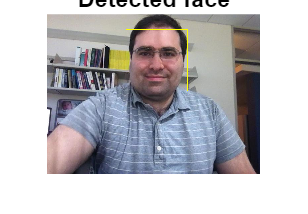

% KLT
% 1. Make a sensor to get face to track

% Make a cascade detector object.
faceSensor = vision.CascadeObjectDetector();

% Retrieve a frame from a video and apply
% the face detection algorithm.
readFileVideo     = VideoReader("tilted_face.avi");
frameOfVideo      = readFrame(readFileVideo);
boundingFrame     = step(faceSensor, frameOfVideo);

% Apply a bounding box around the detected
% face and indicate it visually.
frameOfVideo = insertShape(frameOfVideo, "rectangle", boundingFrame);
figure; imshow(frameOfVideo); title("Detected face");


% Transform the initial bounding box into
% a list of four point - necessary to enable 
% visualisation of the object's rotation.
pointsOfBoundingBox = bbox2points(boundingFrame(1, :));

% 2.Locate facial areas to monitor

pointsMapped = detectMinEigenFeatures(im2gray(frameOfVideo), "ROI", boundingFrame);

% Show the detected points.
figure, imshow(frameOfVideo), hold on, title("Detected features");
plot(pointsMapped);

% 3. Configuring the tracker to track the points

pointTracker = vision.PointTracker("MaxBidirectionalError", 2);

% Initialize the tracker with the initial point locations and the initial
% video frame.
pointsMapped = pointsMapped.Location;
initialize(pointTracker, pointsMapped, frameOfVideo);

% 4. Configuring the vidoe play to show the results
videoPlayer  = vision.VideoPlayer("Position",...
    [100 100 [size(frameOfVideo, 2), size(frameOfVideo, 1)]+30]);

% 5. Tracking the face
initialPoints = pointsMapped;

while hasFrame(readFileVideo)
    % retrieve the next frame
    frameOfVideo = readFrame(readFileVideo);

    % Tracking the points although may be lost.
    [pointsMapped, isFound] = step(pointTracker, frameOfVideo);
    observablePoints = pointsMapped(isFound, :);
    initialInliers = initialPoints(isFound, :);
    
    if size(observablePoints, 1) >= 2 % need at least 2 points
        
        % Estimate the geometric transformation between the initial points
        % and the new points and getting rid of outliers
        [xform, inlierIdx] = estimateGeometricTransform2D(...
            initialInliers, observablePoints, "similarity", "MaxDistance", 4);
        initialInliers    = initialInliers(inlierIdx, :);
        observablePoints = observablePoints(inlierIdx, :);
        
        % Applying the transformation to the bounding box points
        pointsOfBoundingBox = transformPointsForward(xform, pointsOfBoundingBox);
                
        % Enclose the tracked object with a bounding box.
        boundingBoxPolygon = reshape(pointsOfBoundingBox', 1, []);
        frameOfVideo = insertShape(frameOfVideo, "polygon", boundingBoxPolygon, ...
            "LineWidth", 2);
                
        % Show tracked points
        frameOfVideo = insertMarker(frameOfVideo, observablePoints, "+", ...
            "Color", "white");       
        
        % Reset the points
        initialPoints = observablePoints;
        setPoints(pointTracker, initialPoints);        
    end
    
    % Show the annotated video frame by utilising the video player object
    step(videoPlayer, frameOfVideo);
end

% Clean up
release(videoPlayer);

release(pointTracker);